**1.[Overflow Error] **Matlab returns **Inf** when an overflow error in double precision is encountered. Write a script that starts with *n* = 1, calculates *n*! and increases *n* until overflow occurs (number is too big that Matlab can’t handle it). Display the value of *n* that represents the largest factorial that Matlab can handle.

n = 1;
while factorial(n+1) ~= inf
    n = n+1;
end
disp(n);

   170



2. **[Rounding Error]** Approximate the sequence {*π^n*} for *n* = 1 to 18 by rounding π to 1, 2, 4, and 8 decimal places. Calculate the absolute error for each sequence approximation from the sequence that uses *π *with double precision. Plot the errors for each approximate sequence on the same plot with y-axis between 0 and 5. See if you can figure out how to embed smaller plots within the main plot that zoom in on each of the sequences.

n = 1:18;
decimal = [1, 2, 4, 8];
exactValue = pi.^n;
errorList = zeros(length(decimal), length(n));
disp(roundedList);

    3.1000    3.1400    3.1416    3.1416



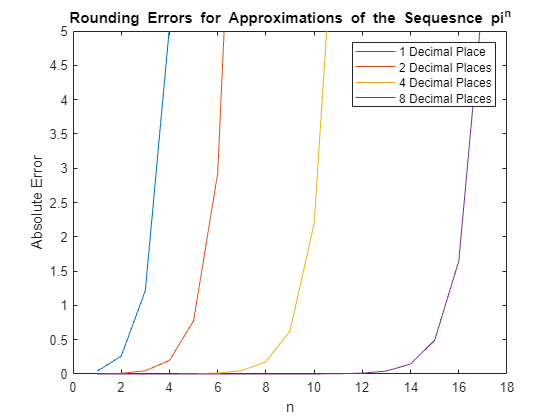

for i = 1:length(decimal)
    rounded = round(pi, decimal(i));
    approxSeq = rounded.^n;
    error = abs(exactValue - approxSeq);
    errorList(i,:) = error;
    plot(n, error);
    ylim([0 5]);
    hold on;
end
hold off
title("Rounding Errors for Approximations of the Sequesnce pi^n");
xlabel("n");
ylabel("Absolute Error");
legend('1 Decimal Place', '2 Decimal Places', '4 Decimal Places', '8 Decimal Places')

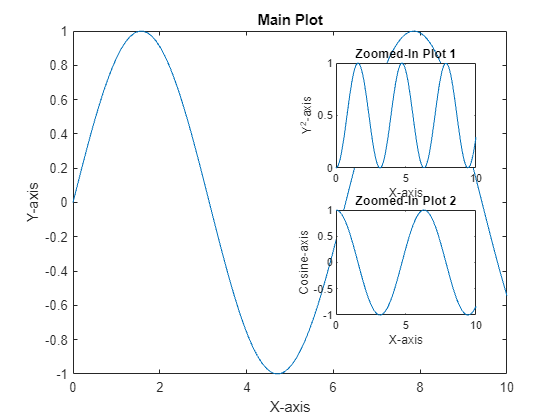

% how to create subplot within main plot
% Create some data for the main plot
x = linspace(0, 10, 100);
y = sin(x);

% Create the main plot
figure;
main_axes = axes;
plot(x, y);
title('Main Plot');
xlabel('X-axis');
ylabel('Y-axis');

% Define positions and sizes for subplots within the main plot
subplot1 = axes('Position', [0.6, 0.6, 0.25, 0.25]); % [left, bottom, width, height]
subplot2 = axes('Position', [0.6, 0.25, 0.25, 0.25]);

% Plot data in the first subplot
axes(subplot1);
plot(x, y.^2);
title('Zoomed-In Plot 1');
xlabel('X-axis');
ylabel('Y^2-axis');

% Plot data in the second subplot
axes(subplot2);
plot(x, cos(x));
title('Zoomed-In Plot 2');
xlabel('X-axis');
ylabel('Cosine-axis');

3. The Maclaurin series for cos(*x*) is 

Plot the cosine function in a thick black line between –2π and 2π. On the same graph plot the Maclaurin series approximation for *n* equal to 2, 4, 8 and 16.

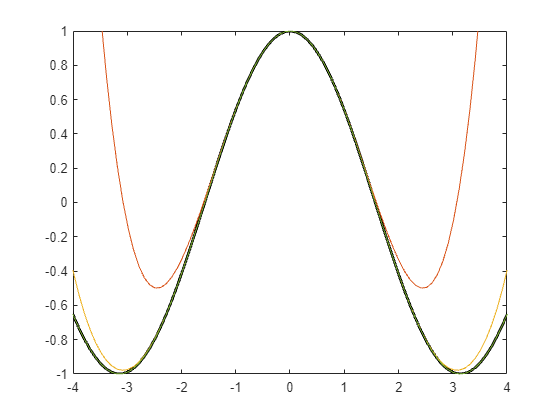

close all;
x = -2*pi:0.1:2*pi;
cos_x = cos(x);
p = plot(x, cos_x, 'k', "LineWidth",2);
xlim([-4, 4]);
ylim([-1,1]);
hold on
n_values = [2, 4, 8, 16];
approxList = zeros(length(n_values), length(x));
for i = 1:length(n_values)
    n = n_values(i);
    approximation = 0;
    for k = 0:n
        approximation = approximation + ((-1)^k*x.^(2*k))/factorial(2*k);
    end
    approxList(i, :) = approximation;
end
for j = 1:length(n_values)
    plot(x, approxList(j, :));
end
hold off

5. **[True vs. Relative Error]** The Maclaurin series for *e^x* is 

Plot the true function from 0 to 5 then on the same graph plot the Maclaurin approximations for *n* equal to 1, 2, 4, 8, and 16. Calculate the true absolute and true relative errors then plot these together in a separate graph.

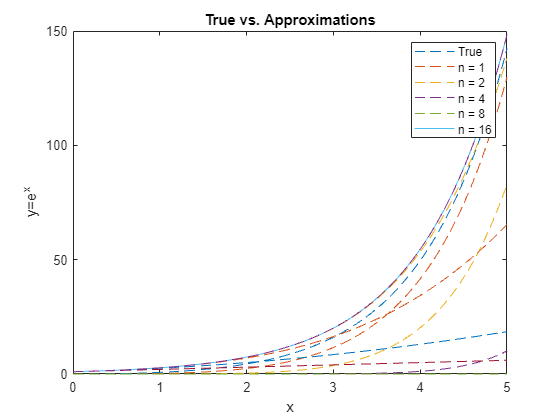

x = linspace(0, 5, 1000);
n_value = [1, 2, 4, 8, 16];
trueFunc = exp(x);
plot(x, trueFunc);
approxList = zeros(length(n_value), length(x));
hold on;
for i = 1:length(n_value)
    n = n_value(i);
    approximation = 0;
    for k = 0:n
        approximation = approximation + x.^k/factorial(k);
    end
    approxList(i, :) = approximation;
end
for j = 1:length(n_value)
    plot(x, approxList(j,:), "--");
end
xlabel("x");
ylabel("y=e^x");
title("True vs. Approximations");
legend("True", "n = 1", "n = 2", "n = 4", "n = 8", "n = 16" )
hold off

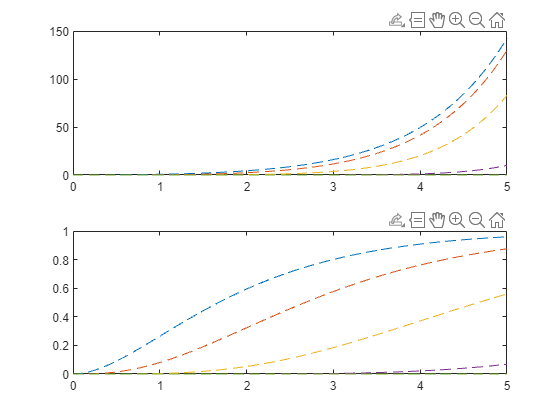

figure;
subplot(2, 1, 1);
absErrorList = zeros(length(n_value), length(x));
for i = 1:length(n_value)
    absError = abs(trueFunc - approxList(i, :));
    absErrorList(i, :) = absError;
end
for j = 1:length(n_value)
    plot(x, absErrorList(j, :), '--');
    hold on;
end
subplot(2, 1, 2);
relativeErrorList = zeros(length(n_value), length(x));
for i = 1:length(n_value)
    relativeError = (trueFunc - approxList(i, :))./trueFunc;
    relativeErrorList(i, :) = relativeError;
end
for j = 1:length(n_value)
    plot(x, relativeErrorList(j, :), '--');
    hold on;
end

**6. [Convergence with Absolute Error Criterion]** The series        

 is convergent. Write a script that finds the value the series converges to by using a loop and the absolute approximate error with a tolerance of 0.0001 (stopping criterion).

% ?????????????????????????????????????????????????????????????????????????????????

7. **[Convergence with Relative Error Criterion] **Write a script that finds the value that the series in question 6 converges to, by using a loop and the relative approximate error with a tolerance of 0.0001 (stopping criterion). Compare the results of this question with question 6.

% ?????????????????????????????????????????????????????????????????????????????????

8. **[Open Method Root Finding]** Write a script that implements the Incremental Search Method, with a step size of 0.1, to approximate the 3 roots to the following equation: 

Choose a sensible initial guess for your algorithm (plotting the function might help you decide).

Find a way to test how closely you approximated the roots.

Can you see why this method is only good for initial bracketing?